Stereo Microphone Array

XSpacing =0.5

XSpacing = 0.5000

YSpacing =0.5 

YSpacing = 0.5000

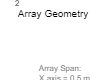


%XSpacing = 0.17; %Front and Back distance between Microphones
MicAngle = 90; %Angle between front mics    


% Assign Frequencies and Propagation Speed
Frequency = 2000; %Test Frequency   
PropagationSpeed = 343; %Speed of Sound

% Create an arbitrary geometry array
Array = phased.ConformalArray();%Create Microphone Array Element
Array.ElementPosition = [(XSpacing/2) -(XSpacing/2) (XSpacing/2) -(XSpacing/2);-(YSpacing/2) -(YSpacing/2) (YSpacing/2) (YSpacing/2);0 0 0 0]; %Create position matrix for each microphone
Array.ElementNormal = [-(MicAngle/2) -(180 - MicAngle/2) (MicAngle/2) (180 - MicAngle/2);0 0 0 0]; %Create angle matrix for each microphone

% Create a custom microphone element
CardMic = phased.CustomMicrophoneElement; %Create Cardioid Microphone Element 
CardMic.FrequencyVector = [0 1e+20]; %Audible spectrum
CardMic.FrequencyResponse = [0 0]; %Flat frequency responce
CardMic.PolarPatternFrequencies = [1000 2000]; 
CardMic.PolarPatternAngles = [-180 -179 -178 -177 -176 -175 -174 -173 -172 -171 -170 -169 -168 -167 -166 -165 -164 -163 -162 -161 -160 -159 -158 -157 -156 -155 -154 -153 -152 -151 -150 -149 -148 -147 -146 -145 -144 -143 -142 -141 -140 -139 -138 -137 -136 -135 -134 -133 -132 -131 -130 -129 -128 -127 -126 -125 -124 -123 -122 -121 -120 -119 -118 -117 -116 -115 -114 -113 -112 -111 -110 -109 -108 -107 -106 -105 -104 -103 -102 -101 -100 -99 -98 -97 -96 -95 -94 -93 -92 -91 -90 -89 -88 -87 -86 -85 -84 -83 -82 -81 -80 -79 -78 -77 -76 -75 -74 -73 -72 -71 -70 -69 -68 -67 -66 -65 -64 -63 -62 -61 -60 -59 -58 -57 -56 -55 -54 -53 -52 -51 -50 -49 -48 -47 -46 -45 -44 -43 -42 -41 -40 -39 -38 -37 -36 -35 -34 -33 -32 -31 -30 -29 -28 -27 -26 -25 -24 -23 -22 -21 -20 -19 -18 -17 -16 -15 -14 -13 -12 -11 -10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180];
CardMic.PolarPattern = [-Inf -82.3663256129284 -70.3257872630862 -63.2832393844453 -58.2872334441572 -54.4128175353661 -51.2479934529581 -48.5729888491337 -46.2566192607348 -44.2142680637425 -42.3881596667952 -40.7370851384172 -39.2306173746889 -37.8456497450421 -36.5642211483328 -35.3720932509569 -34.2577878400194 -33.211916528977 -32.2267023457204 -31.2956308422078 -30.413190799536 -29.5746782621895 -28.7760462019838 -28.0137876274349 -27.284843588859 -26.5865299754775 -25.9164786783496 -25.2725898634227 -24.6529929285625 -24.056014314882 -23.4801507772264 -22.9240470391336 -22.3864769965854 -21.8663278149899 -21.362586400905 -20.8743278352855 -20.4007054365584 -19.9409421854826 -19.4943232938095 -19.0601897384134 -18.6379326141793 -18.2269881843035 -17.8268335271414 -17.4369826953533 -17.0569833166643 -16.6864135766767 -16.3248795333379 -15.9720127202595 -15.62746800239 -15.290921652815 -14.9620696238744 -14.640625989505 -14.3263215388547 -14.0189025038775 -13.7181294058798 -13.4237760079205 -13.1356283616189 -12.8534839383439 -12.5771508359773 -12.3064470534998 -12.0411998265592 -11.7812450179723 -11.5264265578003 -11.2765959282399 -11.0316116890924 -10.7913390400384 -10.5556494163459 -10.324420114994 -10.0975339485101 -9.87487892409266 -9.65634794583611 -9.44183853809294 -9.23125258819864 -9.02449610695746 -8.82147900543944 -8.62211488677517 -8.42632085175674 -8.23401731716229 -8.04512784581945 -7.85957898751066 -7.6773001299026 -7.49822335875273 -7.32228332671045 -7.14941713008818 -6.97956419303 -6.81266615855296 -6.64866678597919 -6.48751185431595 -6.32914907117607 -6.17352798686374 -6.02059991327962 -5.87031784732637 -5.72263639851977 -5.57751172053329 -5.43490144642395 -5.29476462730632 -5.15706167425861 -5.02175430326009 -4.88880548297411 -4.75817938520372 -4.62984133785922 -4.50375778028839 -4.37989622082999 -4.25822519646123 -4.13871423441811 -4.02133381567613 -3.906055340186 -3.79285109376615 -3.6816942165601 -3.57255867297284 -3.46541922300568 -3.36025139491443 -3.25703145912013 -3.1557364033064 -3.05634390864122 -2.9588323270649 -2.86318065958957 -2.76936853555887 -2.67737619281938 -2.58718445875851 -2.498774732166 -2.4121289658788 -2.32722965017153 -2.24405979685659 -2.16260292406047 -2.08284304164445 -2.00476463723955 -1.92835266286778 -1.85359252212269 -1.78047005788426 -1.70897154054406 -1.63908365671838 -1.57079349842788 -1.50408855272374 -1.43895669174114 -1.37538616316217 -1.313365581071 -1.25288391718519 -1.19393049244785 -1.13649496896617 -1.08056734228254 -1.02613793396525 -0.973197384506526 -0.921736646516132 -0.871746978199485 -0.823219937109809 -0.776147374164356 -0.730521427915275 -0.686334519066195 -0.643579345226037 -0.60224887589206 -0.562336347654494 -0.523835259615612 -0.486739369016384 -0.451042687064281 -0.416739474956122 -0.383824240090194 -0.352291732462185 -0.322136941239803 -0.293355091511188 -0.265941641202579 -0.239892278160897 -0.215202917397199 -0.191869698487204 -0.169888983125314 -0.149257352828798 -0.129971606789025 -0.112028759866833 -0.0954260407293674 -0.0801608901258496 -0.0662309593000375 -0.0536341085372268 -0.0423684058438908 -0.03243212575822 -0.0238237482899952 -0.0165419579884047 -0.010585643136597 -0.00595389507190363 -0.00264600763086078 -0.000661476718310808 0 -0.000661476718310808 -0.00264600763086078 -0.00595389507190363 -0.010585643136597 -0.0165419579884047 -0.0238237482899952 -0.03243212575822 -0.0423684058438908 -0.0536341085372268 -0.0662309593000375 -0.0801608901258496 -0.0954260407293674 -0.112028759866833 -0.129971606789025 -0.149257352828798 -0.169888983125314 -0.191869698487204 -0.215202917397199 -0.239892278160897 -0.265941641202579 -0.293355091511188 -0.322136941239803 -0.352291732462185 -0.383824240090194 -0.416739474956122 -0.451042687064281 -0.486739369016384 -0.523835259615612 -0.562336347654494 -0.60224887589206 -0.643579345226037 -0.686334519066195 -0.730521427915275 -0.776147374164356 -0.823219937109809 -0.871746978199485 -0.921736646516132 -0.973197384506526 -1.02613793396525 -1.08056734228254 -1.13649496896617 -1.19393049244785 -1.25288391718519 -1.313365581071 -1.37538616316217 -1.43895669174114 -1.50408855272374 -1.57079349842788 -1.63908365671838 -1.70897154054406 -1.78047005788426 -1.85359252212269 -1.92835266286778 -2.00476463723955 -2.08284304164445 -2.16260292406047 -2.24405979685659 -2.32722965017153 -2.4121289658788 -2.498774732166 -2.58718445875851 -2.67737619281938 -2.76936853555887 -2.86318065958957 -2.9588323270649 -3.05634390864122 -3.1557364033064 -3.25703145912013 -3.36025139491443 -3.46541922300568 -3.57255867297284 -3.6816942165601 -3.79285109376615 -3.906055340186 -4.02133381567613 -4.13871423441811 -4.25822519646123 -4.37989622082999 -4.50375778028839 -4.62984133785922 -4.75817938520372 -4.88880548297411 -5.02175430326009 -5.15706167425861 -5.29476462730632 -5.43490144642395 -5.57751172053329 -5.72263639851977 -5.87031784732637 -6.02059991327962 -6.17352798686374 -6.32914907117607 -6.48751185431595 -6.64866678597919 -6.81266615855296 -6.97956419303 -7.14941713008818 -7.32228332671045 -7.49822335875273 -7.6773001299026 -7.85957898751066 -8.04512784581945 -8.23401731716229 -8.42632085175674 -8.62211488677517 -8.82147900543944 -9.02449610695746 -9.23125258819864 -9.44183853809294 -9.65634794583611 -9.87487892409266 -10.0975339485101 -10.324420114994 -10.5556494163459 -10.7913390400384 -11.0316116890924 -11.2765959282399 -11.5264265578003 -11.7812450179723 -12.0411998265592 -12.3064470534998 -12.5771508359773 -12.8534839383439 -13.1356283616189 -13.4237760079205 -13.7181294058798 -14.0189025038775 -14.3263215388547 -14.640625989505 -14.9620696238744 -15.290921652815 -15.62746800239 -15.9720127202595 -16.3248795333379 -16.6864135766767 -17.0569833166643 -17.4369826953533 -17.8268335271414 -18.2269881843035 -18.6379326141793 -19.0601897384134 -19.4943232938095 -19.9409421854826 -20.4007054365584 -20.8743278352855 -21.362586400905 -21.8663278149899 -22.3864769965854 -22.9240470391336 -23.4801507772264 -24.056014314882 -24.6529929285625 -25.2725898634227 -25.9164786783496 -26.5865299754775 -27.284843588859 -28.0137876274349 -28.7760462019838 -29.5746782621895 -30.413190799536 -31.2956308422078 -32.2267023457204 -33.211916528977 -34.2577878400194 -35.3720932509569 -36.5642211483328 -37.8456497450421 -39.2306173746889 -40.7370851384172 -42.3881596667952 -44.2142680637425 -46.2566192607348 -48.5729888491337 -51.2479934529581 -54.4128175353661 -58.2872334441572 -63.2832393844453 -70.3257872630862 -82.3663256129284 -Inf;-13.9794000867204 -13.9767546834818 -13.9688241094473 -13.9556252347155 -13.9371860534751 -13.9135455018073 -13.8847532060998 -13.8508691654629 -13.8119633723759 -13.768115376524 -13.719413797421 -13.6659557919175 -13.6078464830772 -13.545198357156 -13.4781306355419 -13.4067686285129 -13.3312430775493 -13.2516894927163 -13.1682474913087 -13.0810601435536 -12.9902733306981 -12.8960351202946 -12.7984951629429 -12.6978041141763 -12.5941130845956 -12.487573120782 -12.3783347189552 -12.266547372809 -12.1523591564509 -12.0359163429054 -11.9173630582175 -11.7968409708106 -11.6744890154218 -11.5504431506493 -11.4248361489042 -11.2977974173633 -11.1694528483598 -11.039924697535 -10.9093314879881 -10.7777879386125 -10.6454049147841 -10.5122893995704 -10.3785444836507 -10.244269372182 -10.1095594068994 -9.97450610180848 -9.83919719090543 -9.70371668644232 -9.56814494634636 -9.43255874949105 -9.29703137761106 -9.16163270274425 -9.02642927917567 -8.89148443894691 -8.75685839007979 -8.62260831674574 -8.48878848068997 -8.35545032329365 -8.2226425677263 -8.09041132070549 -7.95880017344075 -7.82785030139444 -7.69760056254287 -7.56808759386813 -7.4393459058534 -7.311407974793 -7.1843043327637 -7.05806365513462 -6.93271284552158 -6.80827711811642 -6.68478007734423 -6.56224379482069 -6.44068888359914 -6.32013456971177 -6.20059876102235 -6.0820981134191 -5.96464809438565 -5.84826304399623 -5.73295623338781 -5.61873992076751 -5.50562540501789 -5.39362307696647 -5.28274246838823 -5.17299229881205 -5.06438052020315 -4.95691435959436 -4.85060035973944 -4.74544441786138 -4.64145182256796 -4.53862728900636 -4.43697499232713 -4.33649859952682 -4.23720129973684 -4.13908583302467 -4.04215451777166 -3.94640927668998 -3.85185166153904 -3.7584828766003 -3.66630380096675 -3.57531500970194 -3.48551679392102 -3.39690917984449 -3.30949194687341 -3.2232646447326 -3.13822660972687 -3.05437698015317 -2.97171471090971 -2.89023858734163 -2.80994723836061 -2.73083914887469 -2.65291267156234 -2.57616603802386 -2.50059736934122 -2.42620468607624 -2.35298591773555 -2.28093891172936 -2.21006144185001 -2.14035121629459 -2.07180588525528 -2.00442304809952 -1.93820026016113 -1.8731350391626 -1.80922487128765 -1.74646721692214 -1.68485951608073 -1.62439919353566 -1.56508366366316 -1.50691033502239 -1.44987661468094 -1.39397991230022 -1.33921764399332 -1.28558723596757 -1.23308612796301 -1.18171177649764 -1.13146165792976 -1.08233327134714 -1.03432414129217 -0.987431820331866 -0.941653891480883 -0.8969879704856 -0.853431707976557 -0.810982791496421 -0.769638947410139 -0.729397942703643 -0.690257586677108 -0.652215732538459 -0.615270278902521 -0.579419171200914 -0.544660403007521 -0.510992017284097 -0.478412107550346 -0.446918818982535 -0.416510349444533 -0.387184950454898 -0.358940928093463 -0.331776643850676 -0.305690515422762 -0.280681017455569 -0.256746682239866 -0.2338861003606 -0.212097921302559 -0.191380854014683 -0.171733667435134 -0.153155190979131 -0.135644314991379 -0.119199991164852 -0.10382123292751 -0.089507115798474 -0.0762567777150287 -0.0640694193317454 -0.0529443042928828 -0.0428807594791727 -0.0338781752299362 -0.0259360055414469 -0.0190537682423111 -0.0132310451465926 -0.0084674821852787 -0.0047627895166346 -0.00211674161588518 -0.000529177344589105 0 -0.000529177344589105 -0.00211674161588518 -0.0047627895166346 -0.0084674821852787 -0.0132310451465926 -0.0190537682423111 -0.0259360055414469 -0.0338781752299362 -0.0428807594791727 -0.0529443042928828 -0.0640694193317454 -0.0762567777150287 -0.089507115798474 -0.10382123292751 -0.119199991164852 -0.135644314991379 -0.153155190979131 -0.171733667435134 -0.191380854014683 -0.212097921302559 -0.2338861003606 -0.256746682239866 -0.280681017455569 -0.305690515422762 -0.331776643850676 -0.358940928093463 -0.387184950454898 -0.416510349444533 -0.446918818982535 -0.478412107550346 -0.510992017284097 -0.544660403007521 -0.579419171200914 -0.615270278902521 -0.652215732538459 -0.690257586677108 -0.729397942703643 -0.769638947410139 -0.810982791496421 -0.853431707976557 -0.8969879704856 -0.941653891480883 -0.987431820331866 -1.03432414129217 -1.08233327134714 -1.13146165792976 -1.18171177649764 -1.23308612796301 -1.28558723596757 -1.33921764399332 -1.39397991230022 -1.44987661468094 -1.50691033502239 -1.56508366366316 -1.62439919353566 -1.68485951608073 -1.74646721692214 -1.80922487128765 -1.8731350391626 -1.93820026016113 -2.00442304809952 -2.07180588525528 -2.14035121629459 -2.21006144185001 -2.28093891172936 -2.35298591773555 -2.42620468607624 -2.50059736934122 -2.57616603802386 -2.65291267156234 -2.73083914887469 -2.80994723836061 -2.89023858734163 -2.97171471090971 -3.05437698015317 -3.13822660972687 -3.2232646447326 -3.30949194687341 -3.39690917984449 -3.48551679392102 -3.57531500970194 -3.66630380096675 -3.7584828766003 -3.85185166153904 -3.94640927668998 -4.04215451777166 -4.13908583302467 -4.23720129973684 -4.33649859952682 -4.43697499232713 -4.53862728900636 -4.64145182256796 -4.74544441786138 -4.85060035973944 -4.95691435959436 -5.06438052020315 -5.17299229881205 -5.28274246838823 -5.39362307696647 -5.50562540501789 -5.61873992076751 -5.73295623338781 -5.84826304399623 -5.96464809438565 -6.0820981134191 -6.20059876102235 -6.32013456971177 -6.44068888359914 -6.56224379482069 -6.68478007734423 -6.80827711811642 -6.93271284552158 -7.05806365513462 -7.1843043327637 -7.311407974793 -7.4393459058534 -7.56808759386813 -7.69760056254287 -7.82785030139444 -7.95880017344075 -8.09041132070549 -8.2226425677263 -8.35545032329365 -8.48878848068997 -8.62260831674574 -8.75685839007979 -8.89148443894691 -9.02642927917567 -9.16163270274425 -9.29703137761106 -9.43255874949105 -9.56814494634636 -9.70371668644232 -9.83919719090543 -9.97450610180848 -10.1095594068994 -10.244269372182 -10.3785444836507 -10.5122893995704 -10.6454049147841 -10.7777879386125 -10.9093314879881 -11.039924697535 -11.1694528483598 -11.2977974173633 -11.4248361489042 -11.5504431506493 -11.6744890154218 -11.7968409708106 -11.9173630582175 -12.0359163429054 -12.1523591564509 -12.266547372809 -12.3783347189552 -12.487573120782 -12.5941130845956 -12.6978041141763 -12.7984951629429 -12.8960351202946 -12.9902733306981 -13.0810601435536 -13.1682474913087 -13.2516894927163 -13.3312430775493 -13.4067686285129 -13.4781306355419 -13.545198357156 -13.6078464830772 -13.6659557919175 -13.719413797421 -13.768115376524 -13.8119633723759 -13.8508691654629 -13.8847532060998 -13.9135455018073 -13.9371860534751 -13.9556252347155 -13.9688241094473 -13.9767546834818 -13.9794000867204];
Array.Element = CardMic;


% Create Figure
% Plot Array Geometry
figure(1)
viewArray(Array,'ShowNormal',true,...
    'ShowTaper',false,'ShowIndex','All',...
    'ShowLocalCoordinates',true,'ShowAnnotation',true,...
    'Orientation',[0;0;0]);
xlim([-0.125 0.115])
ylim([-0.120 0.120])
zlim([-0.137 0.103])
view([90 90.000])

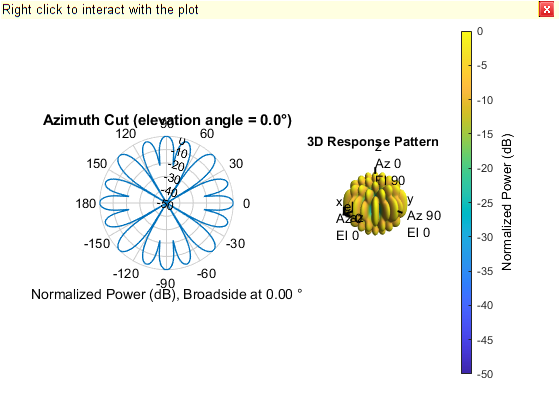


% Calculate Steering Weights
Freq3D = Frequency;
% Find the weights
w = ones(getNumElements(Array), length(Frequency));

% Plot 3d graph
format = 'polar';
plotType = 'powerdb';
figure(2);
subplot(1,2,2)
pattern(Array, Freq3D, 'PropagationSpeed', PropagationSpeed,...
    'CoordinateSystem', format,'weights', w(:,1),...
    'ShowArray',false,'ShowLocalCoordinates',true,...
    'ShowColorbar',true,'Orientation',[0;0;0],...
    'Type', plotType);

% Plot 2d azimuth graph
format = 'polar';
cutAngle = 0;
plotType = 'powerdb';
plotStyle = 'Overlay';
%figure(3);
subplot(1,2,1)
pattern(Array, Frequency, -180:180, cutAngle, 'PropagationSpeed', PropagationSpeed,...
    'CoordinateSystem', format ,'weights', w, ...
    'Type', plotType, 'PlotStyle', plotStyle);



%Calculate the magnitude responce at different frequencies
%Responce = Array(FREQ, ANG) 
Resp = Array(2000, [40; 80]); 
ICLD = mag2db(Resp(2)/Resp(1));

